# Moving Average and Notch Filters

## Input Signals and Noise

### Input Signal

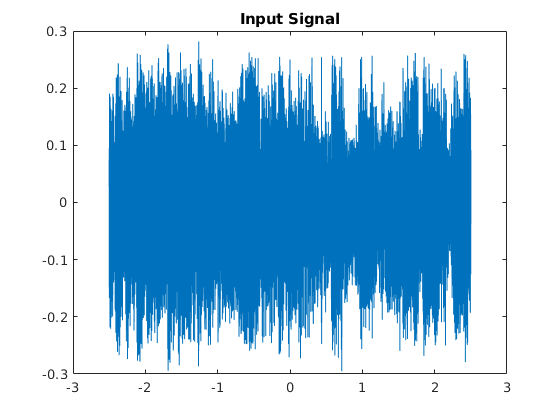

[Data,Fs] = audioread("msmn1.wav");
Ts = 1/Fs;
xn = Data;
Ns = size(xn);
Ns = Ns(1);
n = linspace(-Ns/2,Ns/2,Ns);
t = (Ts*n)';
plot(t,xn)
title('Input Signal');
hold off

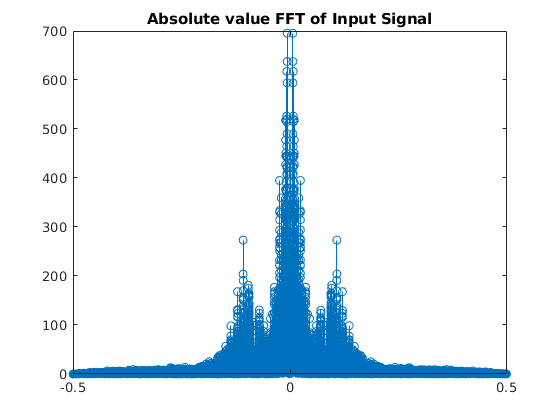

Xz = fft(xn);
fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(fm,fftshift(abs(Xz)))
title('Absolute value FFT of Input Signal')
hold off

### Sinsodial Noisy Signal

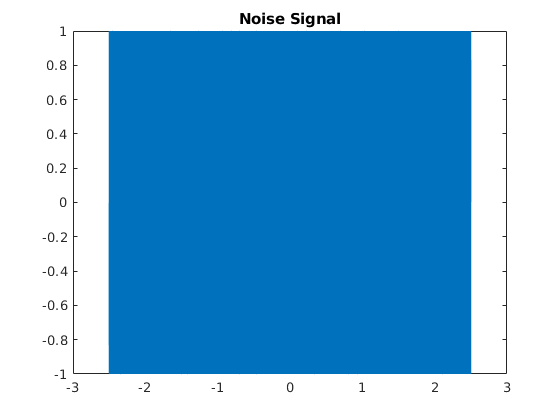

n = linspace(-Ns/2,Ns/2,Ns);
t = (Ts*n)';
f2 = 15000;
nn = sin(2*pi*f2*t);
plot(t,nn)
title('Noise Signal');
hold off

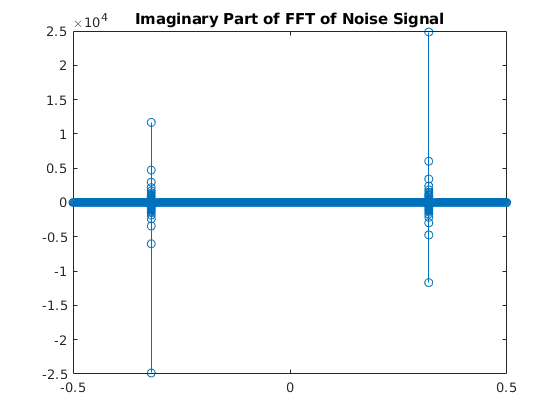

Nz = fft(nn);
Ns = size(nn);
Ns = Ns(1);
fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(fm,fftshift(imag(Nz)))
title('Imaginary Part of FFT of Noise Signal')
hold off

### Resultant Signal

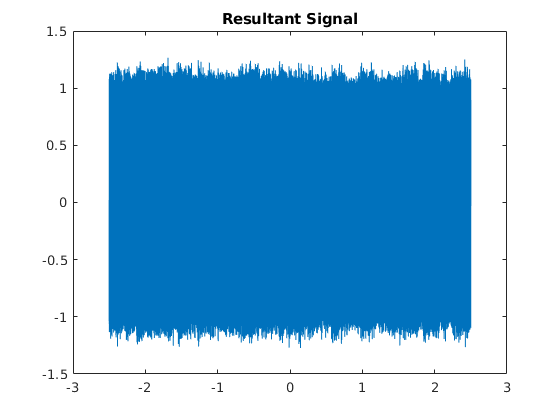

rn = xn + nn;
plot(t,rn)
title('Resultant Signal');
hold off

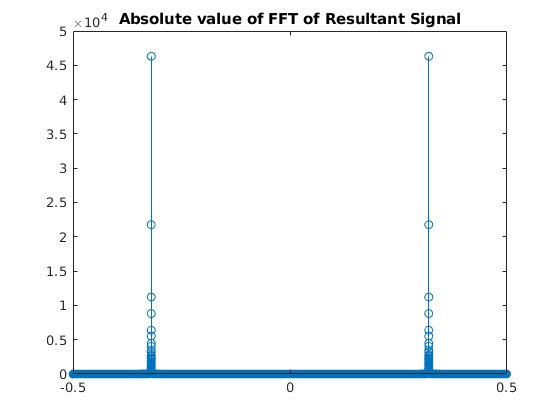

Rz = fft(nn);
Ns = size(nn);
Ns = Ns(1);
fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(fm,fftshift(abs(Rz)))
title('Absolute value of FFT of Resultant Signal')
hold off

### Applying Moving Average Filter

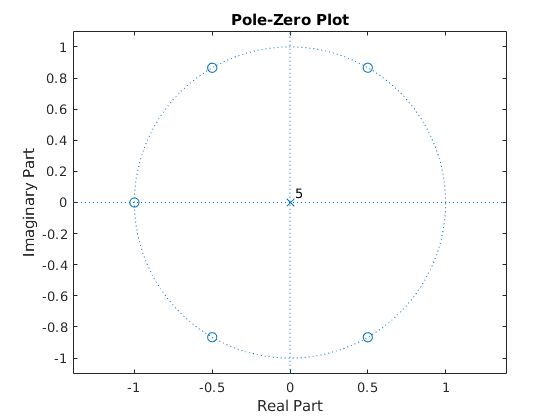

Output = MovingAverageFilter(rn,6);

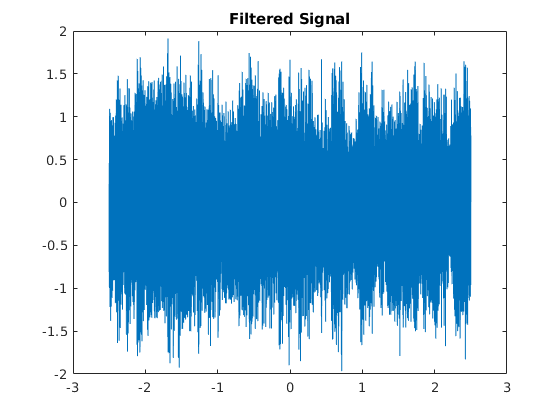

plot(t,Output)
title('Filtered Signal');
hold off

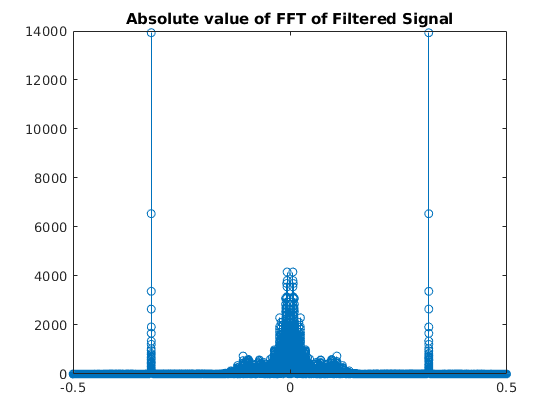

Oz = fft(Output);
Ns = size(Output);
Ns = Ns(1);
fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(fm,fftshift(abs(Oz)))
title('Absolute value of FFT of Filtered Signal')
hold off

audiowrite('MAF_Filtered_Signal.wav', Output, Fs)

### Applying Notch Filter

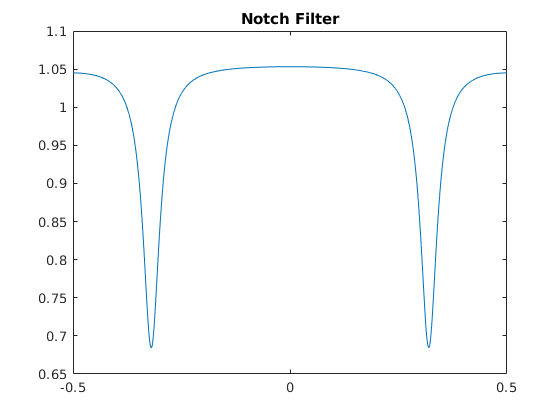

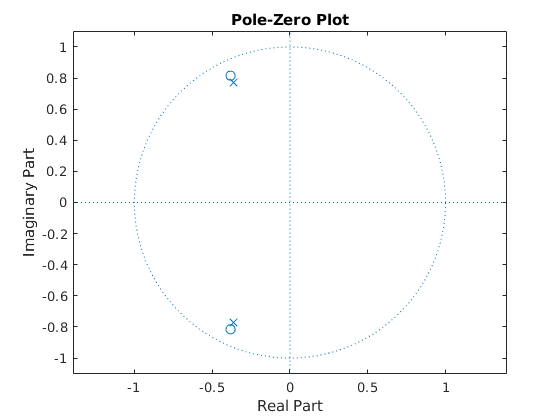

w = 2*pi*f2/Fs;
Z = 0.9*exp(1j*w);
P = 0.85*exp(1j*w);
Output = NotchFilter(rn,Z,P,Ns);

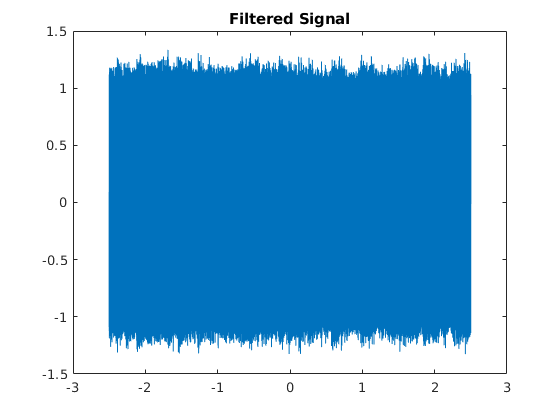

plot(t,Output)
title('Filtered Signal');
hold off

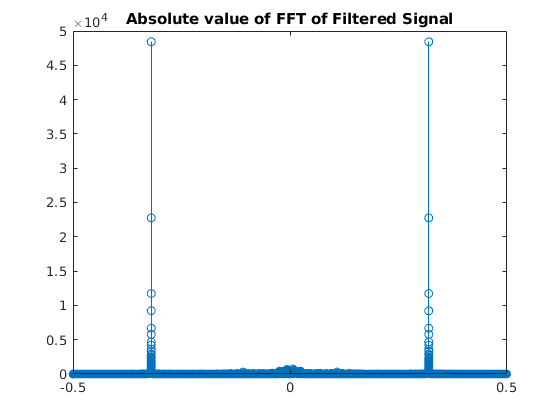

Oz = fft(Output);
Ns = size(Output);
Ns = Ns(1);
fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(fm,fftshift(abs(Oz)))
title('Absolute value of FFT of Filtered Signal')
hold off

audiowrite('Notch_Filtered_Signal.wav', Output, Fs)

### M-Point Moving Average Filter

function Output = MovingAverageFilter(Signal,M)
    Filter = ones(1,M)';
    r = 1;
    Num = r * ones(M,1)';
    Den = ones(1,1)';
    H = zplane(Num,Den);
    title('Pole-Zero Plot')
    Output = conv(Signal,Filter,'same');
end

### Notch Filter

function Output = NotchFilter(Signal,Zero,Pole,Ns)
    r = 1;
    w = linspace(-pi,pi,Ns);
    Z1 = Zero;
    Z2 = conj(Zero);
    P1 = Pole;
    P2 = conj(Pole);
    Hz = @(z) [(z-Z1)*(z-Z2)]/[(z-P1)*(z-P2)];
    Hz_w = arrayfun(Hz,(r * exp(1j*w))');
    fm = (1*(-Ns/2:(Ns/2)-1)/Ns)';
    figure(1)
    plot(fm,(abs(Hz_w)))
    title('Notch Filter')
    figure(2)
    H = zplane([1 -1*(Z1+Z2) Z1*Z2],[1 -1*(P1+P2) P1*P2]);
    title('Pole-Zero Plot')
    Ow = fft(Signal) .* Hz_w;
    Output = real(ifft(Ow));
end